# Projektovanje kontrolera na bazi inverzije dinamike za pracenje reference

clc;
close all;
clear variables;

[G, A, B, H, ue] = linearizacija();
s = tf('s');

## Inverzija dinamike na bazi pracenja reference

G

G =
 
      2646.8 (s-606.3)
  -------------------------
  (s^2 + 40.92s + 1.618e04)
 
Continuous-time zero/pole/gain model.



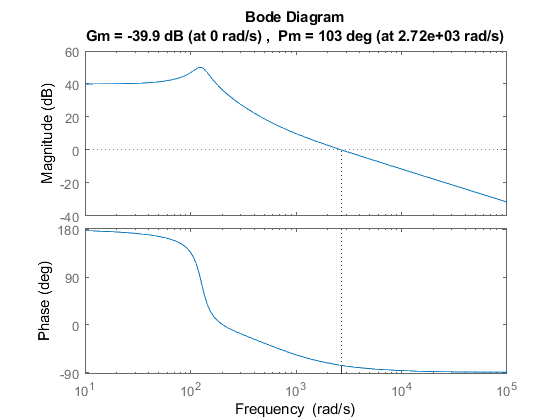

figure()
margin(G)

[w_z, gain] = zero(G);
poles = pole(G);
w_ogranicenje = w_z/4;
G_approx = zpk(-w_z, poles, gain)

G_approx =
 
      2646.8 (s+606.3)
  -------------------------
  (s^2 + 40.92s + 1.618e04)
 
Continuous-time zero/pole/gain model.



w1 = w_ogranicenje

w1 = 151.5773

K_pracenje_ref = -w1/s * G_approx^(-1)

K_pracenje_ref =
 
  -0.057268 (s^2 + 40.92s + 1.618e04)
  -----------------------------------
              s (s+606.3)
 
Continuous-time zero/pole/gain model.



W = minreal(K_pracenje_ref*G)

W =
 
  -151.58 (s-606.3)
  -----------------
     s (s+606.3)
 
Continuous-time zero/pole/gain model.



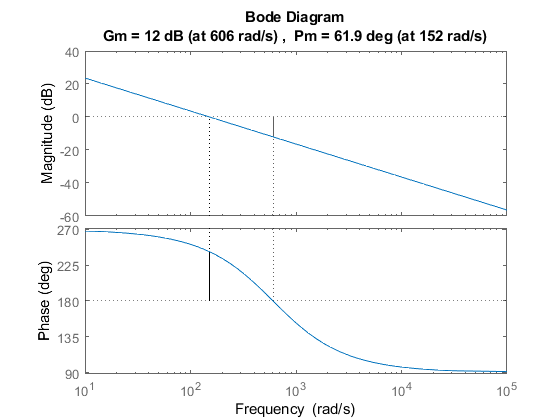

figure()
margin(W)

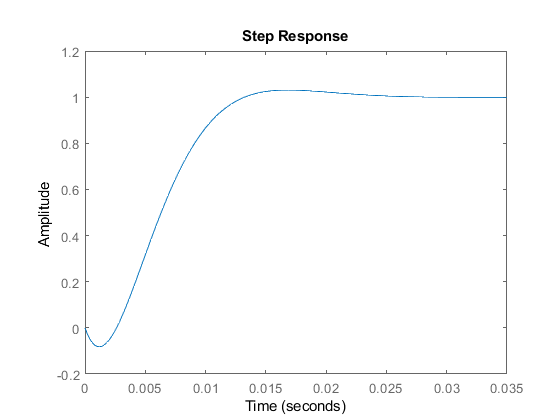

figure()
step(W/(W + 1))